#  ENME462 Studio 10 Root Locus Compensator Design

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM; Section 0103 F 10:00AM - 11:50AM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

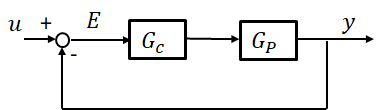

**Close-loop transfer function:**


$$T(s)=\frac{G_c(s)G_p(s)}{1+G_c(s)G_p(s)}$$


**Characteristic equation :**


$$1+G_c(s)G_p(s)=0$$


Magnitude condtion:


$$|G_c(s)G_p(s)|=1$$


Phase condition:


$$\angle G_c(s)G_p(s)=180^o$$


## Response:

***1) Transient response (unity step input)***

First order system $T(s)=\frac{a}{s+a}=\frac{1}{\tau s+1}$

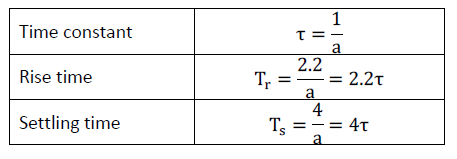

Second order system $T(s)=\frac{\omega_{n}^{2}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}$

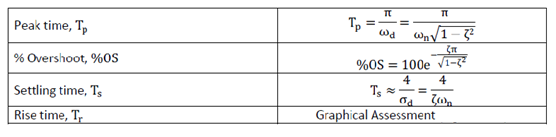

***2) Steady-state error (unity feedback)***

Position constant: $K_p=\lim_{s\rightarrow0}G(s)$        Velocity constant: $K_v=\lim_{s\rightarrow0}sG(s)$        Acceleration constant: $K_a=\lim_{s\rightarrow0}s^2G(s)$

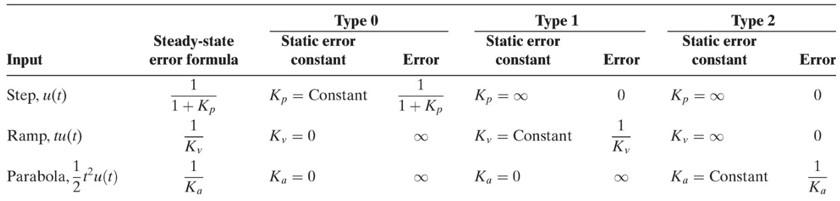

## Compensators: 

**1) Transient Response Compensators**

*i) ****PD**** compensators: *


$$G_c(s)=K_P+K_Ds=K_D(s+K_P/K_D)$$


PD compensator improves the ransient response via *re-shaping* the original system's root locus. An additional zero provides 1 DoF to adjust the root locus angle condtion.

*ii) ****Lead**** compensators*


$$G_c(s)=K\frac{s+z_c}{s+p_c}, \qquad |p_c| <|z_c|$$


Lead compensator improves the transient response via *re-shaping* the original system's root locus. An additional zero/pole pair is placed at a location so that the root locus angle condition can be satisfied at the target closed-loop poles.

**2) Steady-state error Compensators **

*i) ****PI**** compensators*


$$G_c(s)=K_P+\frac{K_I}{s}=\frac{K_P(s+K_i/K_P)}{s}$$


PI compensator adds a pole at he origin and a zero close to the origin to prevent the additional pole from significantly distorting the shape of the original system's root locus. 

ii) **Lag** compensators

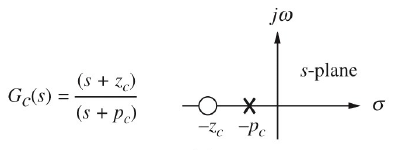

Lag compensator increase the statc error constants, without distorting the shape of the original systems' root locus.

## Example 2 

Consider the unity-feedback system shown below with open-loop transfer function


$$G(s)=\frac{K}{s(s+1)(s^2+10s+26)}$$


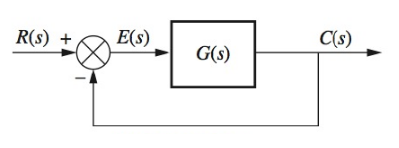

i) Find the settling time for the system if it is operating with 15% OS.

% define the transfer function of the plant %
s = zpk('s');
Gp = 1/(s * (s+1) * (s^2+10*s+26)) 
% get the root locus of the plant %
rlocus(Gp)
sgrid
% from root locus the position of close loop pole w/ 15% OS %
p_re = 0.372;                   % real part of the pole
p_im = 0.615;                   % imaginary part of the pole
% find the setting time 


Gp =
 
             1
  ------------------------
  s (s+1) (s^2 + 10s + 26)
 
Continuous-time zero/pole/gain model.



Ts = 4/abs(p_re)

ii) Develop a cascade cotroller so that the setting time is less than 7s. Specifically, find the zero of the compensator and the gain K, assuming that the pole of the compensator is located at s = -15.

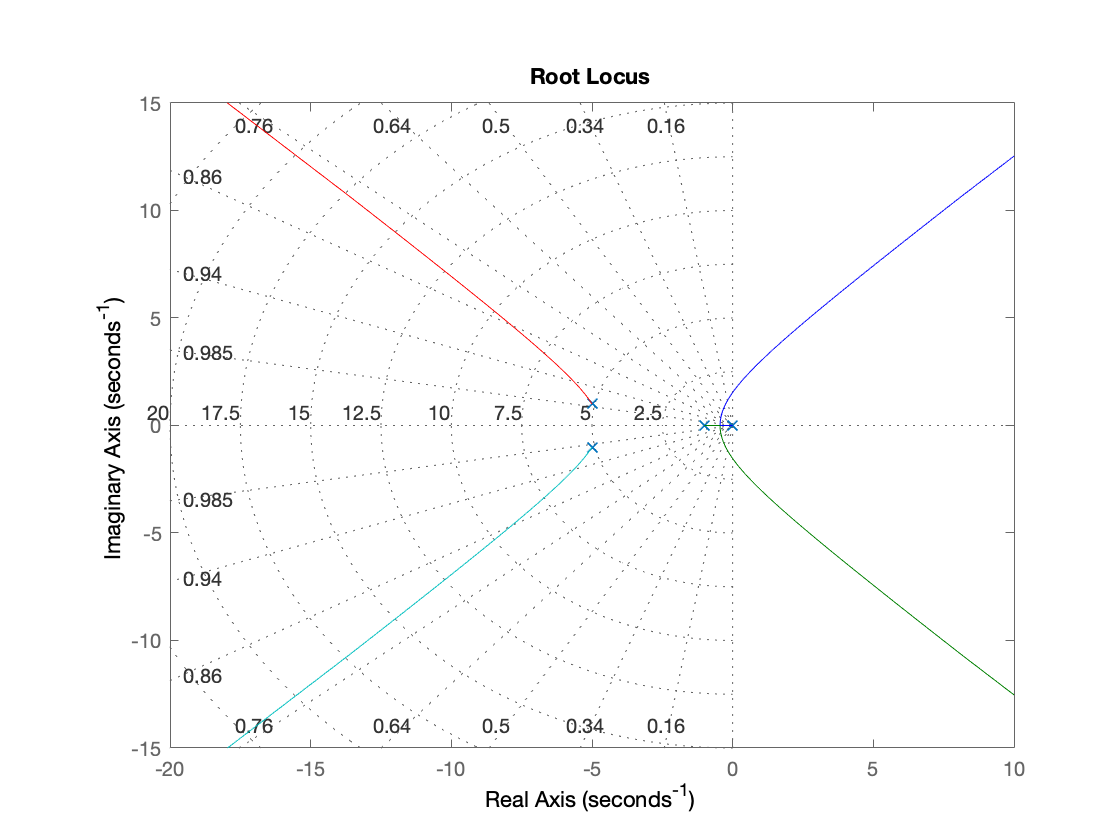

% desired pole position % 
Ts = 7;                         % desired setting time

Po_re = 4/Ts                    % real part of P_desired
Po_im = p_im/p_re * Po_re       % imag part of P_desired
Po = -Po_re + Po_im*1j          % P_desired
% design the pole & zero of the lead compensator %
Pc = 15;                        % lead controller pole

Ts = 10.7527

r2d = 180/pi;                   % radian to degree
ag1 = angle(Po)*r2d             % angle of s
ag2 = angle(Po+1)*r2d           % angle of (s+1)
ag3 = angle(Po^2+10*Po+26)*r2d  % angle of (s^2+10*s+26)

Po_re = 0.5714

ag4 = angle(Po+Pc)*r2d          % angle of (s+p_c)

Po_im = 0.9447

agu = ag1+ag2+ag3+ag4           % angle of uncompensated system

Po =   -0.5714 + 0.9447i


agz = agu-180                   % compensate angle
Zc =  Po_im/tand(agz) +Po_re    % lead controller zeros
% design the gain of the lead compensator
Gc = (s+Zc)/(s+Pc);             % Lead compensator without K

ag1 = 121.1688

G = Gc*Gp

ag2 = 65.5982

rlocus(G)                       % Root Locus of open-loop system

ag3 = 22.9921

sgrid

ag4 = 3.7461

K = 207.512;                    % from RL find the gain

agu = 213.5052

Gc = K*Gc

agz = 33.5052

Zc = 1.9984

iii) Plot the step response of the compensated system and determine the transient response characteristics.

% step response of close-loop system
Gf = Gc*Gp
T = feedback(Gf,1)


G =
 
             (s+1.998)
  -------------------------------
  s (s+15) (s+1) (s^2 + 10s + 26)
 
Continuous-time zero/pole/gain model.



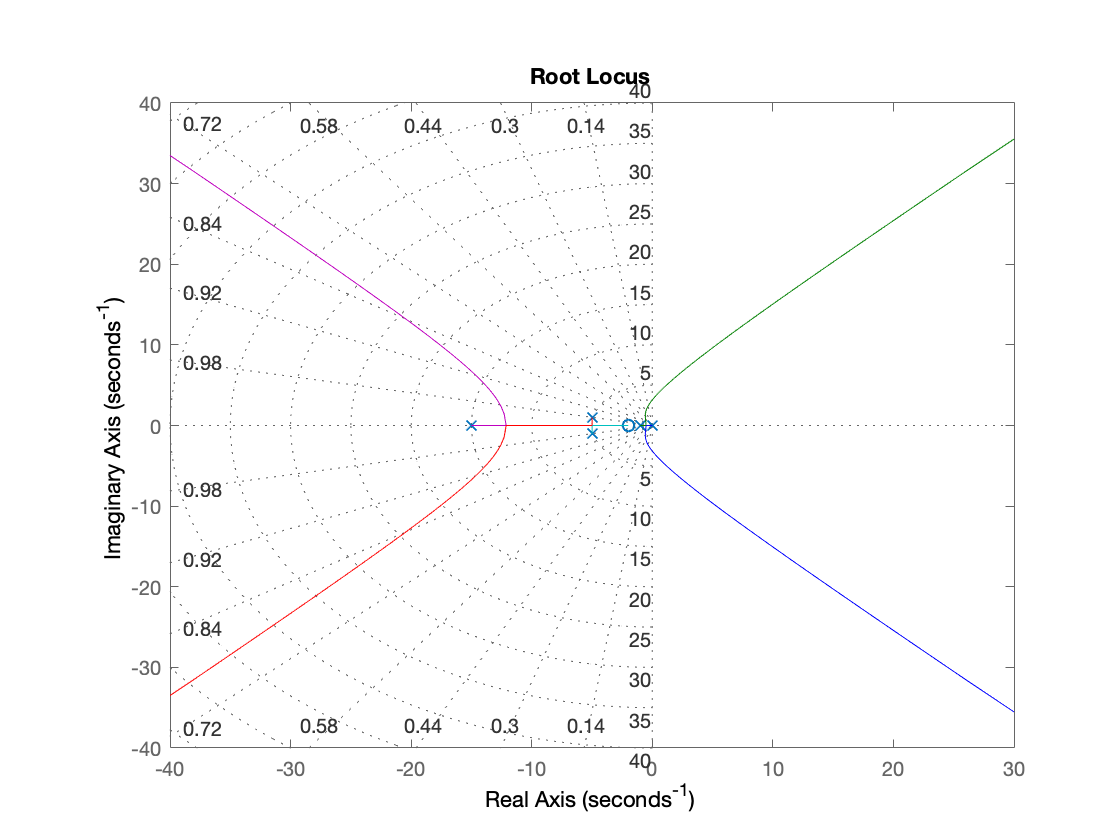


Gc =
 
  207.51 (s+1.998)
  ----------------
       (s+15)
 
Continuous-time zero/pole/gain model.




Gf =
 
         207.51 (s+1.998)
  -------------------------------
  s (s+15) (s+1) (s^2 + 10s + 26)
 
Continuous-time zero/pole/gain model.




T =
 
                   207.51 (s+1.998)
  --------------------------------------------------
  (s+14.87) (s+6.44) (s+3.549) (s^2 + 1.143s + 1.22)
 
Continuous-time zero/pole/gain model.



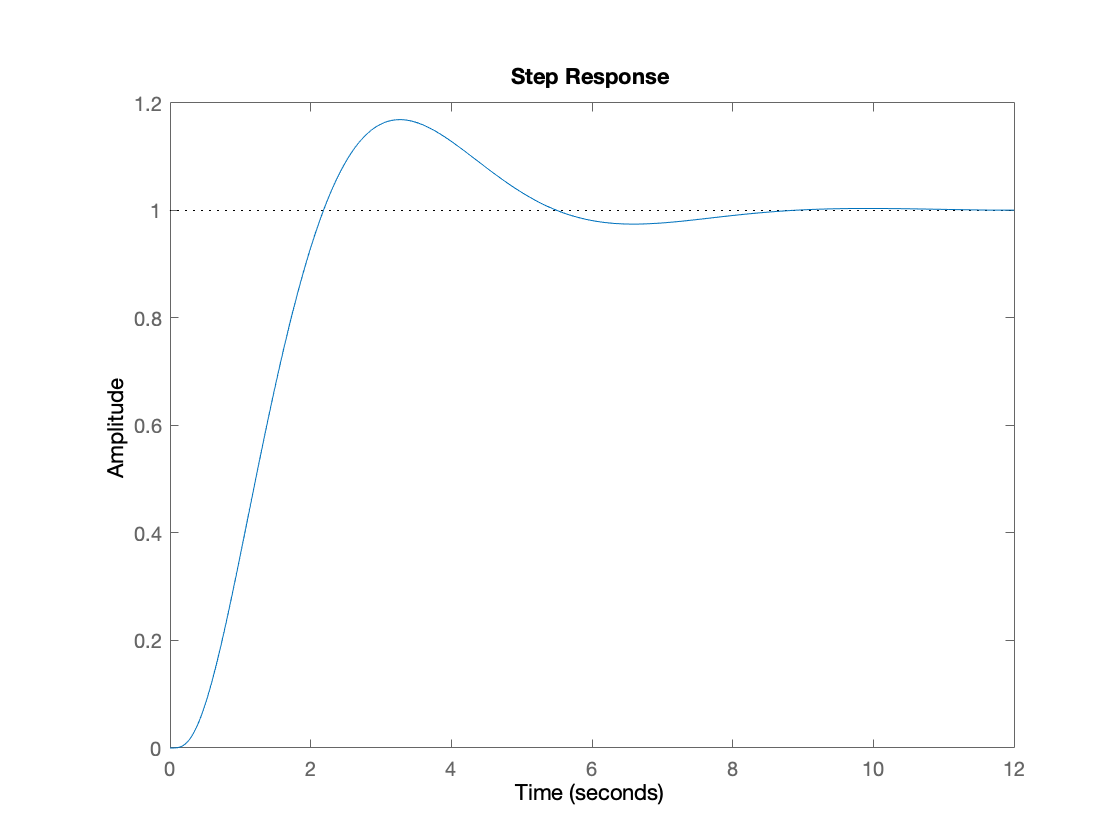

ans = struct with fields:
        RiseTime: 1.3846
    SettlingTime: 7.2672
     SettlingMin: 0.9007
     SettlingMax: 1.1690
       Overshoot: 16.9018
      Undershoot: 0
            Peak: 1.1690
        PeakTime: 3.2608


step(T);
stepinfo(T)

## Exercise 1

Consider the unity feedback system with 


$$G(s)=\frac{K}{(s+1)(s+3)(s+10)}$$


Assume for the remainder of this problem that the system operates with a damping ratio 0.4.

i) Plot the root locus for the system as the gain K is varied

ii) Determine the value of K that will yield a damping ratio 0.4 and determine the corresponding % OS

iii) Determine the steady state error due to a step input for the value of K you found in ii)

iv) Design a PI compensator to drive the step response error to zero while 

maintaining operation with damping ratio 0.4 for the following two cases

a) compensator zero at s=-0.1

b) compensator zero at s=-0.7

v) Compare the specifications of the uncompensated system and each one of the compensated systems(settling time, percent overshoot, steady state error)

vi) Simulate each one of the systems using MATLAB and plot the step response for the uncompensated system and the two compensated systems.

## Exercise 2

Consider the unity feedback system with 


$$G(s)=\frac{K}{(s+4)(s+6)(s+10)}$$


i) Use MATLAB along with hand calculations to design a PID compensator so that the closed-loop system will have % OS <25% and Ts < 2 sec for a step input and zero steady-state error for step and ramp inouts.

ii) Plot the root locus of the compensated system in i) and the step response and show that the specifications are met.